% beamforming再出发
clc;clear;close all

- 标准的格林函数，管道静止声源识别

## 标准的格林函数，管道静止声源识别

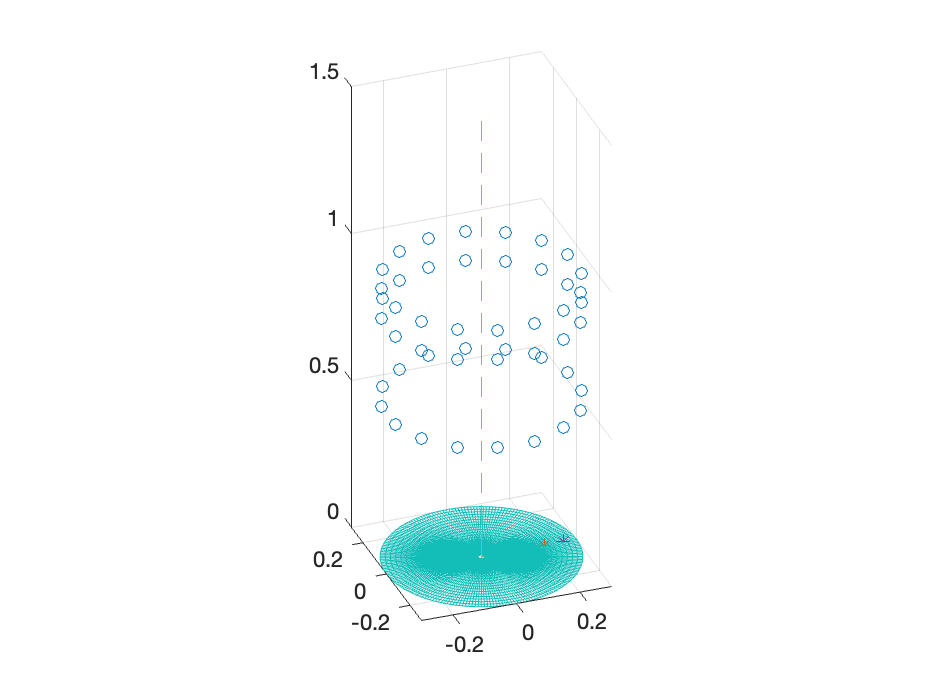

load('database/mics_loc.mat')
% r,theta,x
% 三排传声器
% z=0.54，0.84，0.94


mics_x=mics_loc(:,1).*cos(mics_loc(:,2));mics_y=mics_loc(:,1).*sin(mics_loc(:,2));%Xnet
mics_z=mics_loc(:,3);

figure;plot3(mics_x,mics_y,mics_z,'o')
axis equal
hold on
% 声源面
plot3(0.2,0,0,'*'); plot3([0.2 0],[0 0],[0 0],'-');
plot3(0.26,0,0,'*');plot3([0.26 0],[0 0],[0 0],'-');
plot3([0 0],[0 0],[0 1.5],'--');

grid on

% 重建面
xr2=linspace(0.01,0.3,20);
theta2=linspace(0,360,200);
xr=xr2'*cos(theta2*pi/180);yr=xr2'*sin(theta2*pi/180);%Xnet
h1 = mesh(xr,yr,zeros(20,200));% plot in dB unit,
view([-20.26 29.62])

测试数据处理：

导入数据，暂时基于静止声源的。运动声源主频附近会出现多普勒效应。间隔为1Hz，转动为60rpm。

subfunction_path1='subfunction_0_plot';
addpath(subfunction_path1);
[fname,location]=uigetfile({'*.mat';'*.*'},'mat参数文件读取','MultiSelect','on');%MultiSelect单选
Data = importdata(fullfile(location,char(fname))); %选择文件导入数据
%Data = importdata('database/12同时工作/test20210122_test2_12_1000_1_1.mat');
para=strsplit(fname,'_');

freq=str2num(para{4})

freq = 6000


disp([para{4},'Hz']);

6000Hz


%1——一端开口带障板，另一端吸声。2——一端开口无障板，另一端吸声。3——两端吸声
if para{2}=='test1'
    disp("一端开口带障板，另一端吸声")
elseif para{2}=='test2'
    disp("一端开口无障板，另一端吸声")
elseif para{2}=='test3'
    disp("两端吸声")
end

一端开口无障板，另一端吸声



if para{3}=='1'
    disp("1号扬声器工作")
elseif para{3}=='2'
    disp("2号扬声器工作")
elseif para{3}=='2'
    disp("1号和2号同时扬声器工作")
end

1号扬声器工作






Data_1=Data(:,1:16);Data_2=Data(:,17:32);Data_3=Data(:,33:48);

Fs = 16384;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = length(Data);             % Length of signal
t = (0:L-1)*T;        % Time vector




K = 100;
nFFT = 128;

R = CSM(Data.', freq, Fs, nFFT, K);

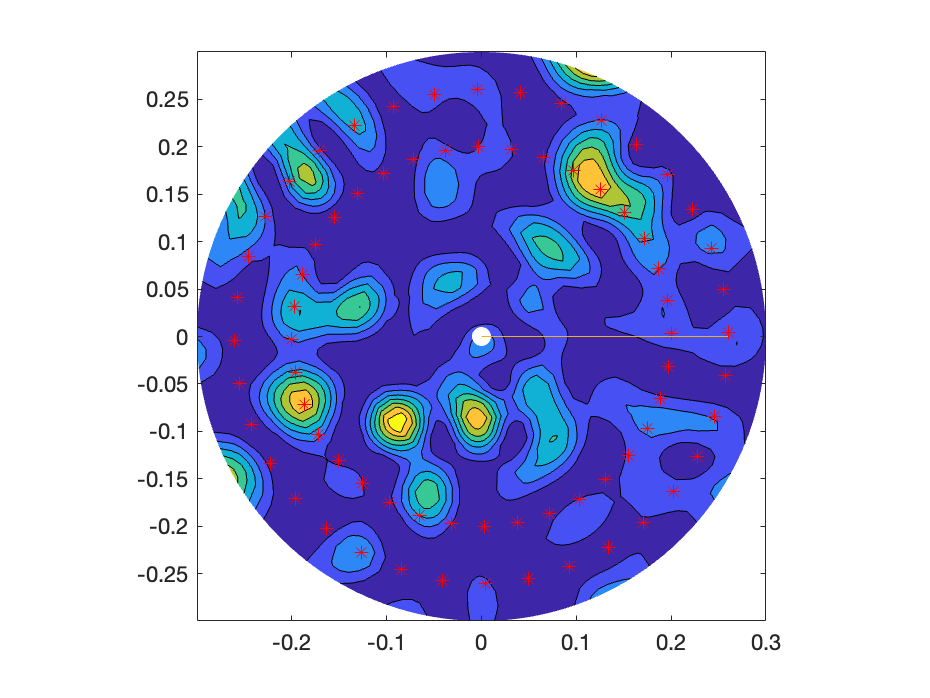

mics=[mics_x mics_y mics_z+0.0];  %调焦距

[hn,gn] = steeringfunction(mics,freq,xr2,theta2);
% Number of microphones in array
N_mic = size(hn,3);


% DAS imaging
for ii = 1:size(gn,1)
    for jj = 1:size(gn,2)
        e = squeeze(gn(ii,jj,:));
        DAS_result(ii,jj) = dot(e,R*e)/(N_mic^2-N_mic);
    end
end

figure; 
h1 = contourf(xr,yr,real(DAS_result));% plot in dB unit,
hold on

axis equal
for theta=[1:10:360]
plot(0.2*cos(theta/180*pi),0.2*sin(theta/180*pi),'*','Color','r'); hold on
plot(0.26*cos(theta/180*pi),0.26*sin(theta/180*pi),'*','Color','r');plot3([0.26 0],[0 0],[0 0],'-');
end